**Convoluzione - Filtro di Media (Blur)**

- **Funzione di libreria**

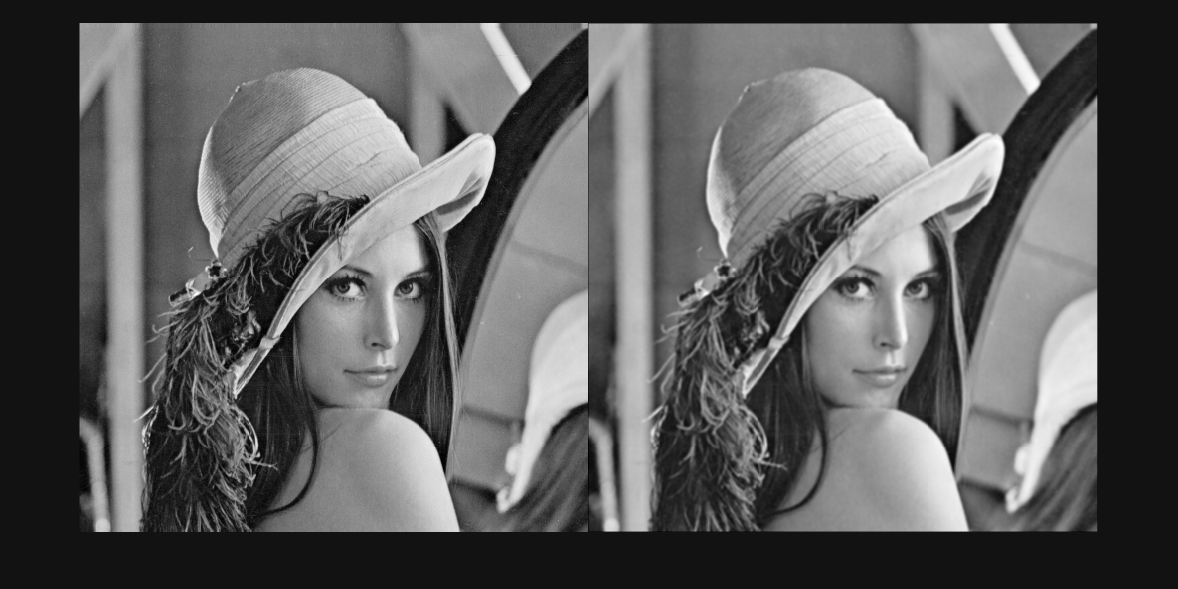

% Creo un kernel 5x5 dove gli elementi sono 1/25
k_blur = fspecial("average",3);
I = rgb2gray(imread("imgs/lena.png"));

% Applico il filtro mediano
img_blur = conv2(I,k_blur,"same");
imshowpair(I,img_blur,"montage");

        2. **Algoritmo per filtro di convoluzione (senza gestione del bordo)**

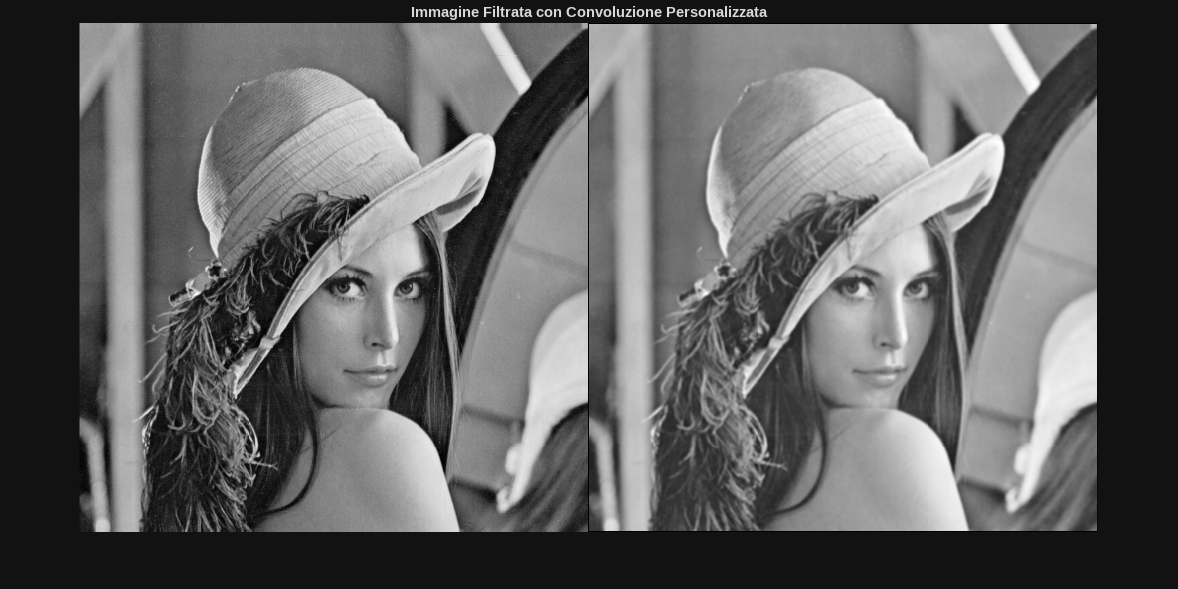

function output = my_conv(img,kernel)
% Ottieni dimensione dell'immagine e del kernel
[h,w] = size(img);
[hk,wk] = size(kernel);

% Inizializza la matrice output
output = zeros(h,w,"single");

hk2 = floor(hk / 2);
wk2 = floor(wk / 2);

% Itera sui pixel interni (ignora bordo)
for i = hk2 + 1 : h - hk2
    for j = wk2 + 1 : w - wk2

        % Inizializza tmp per accumulare i risultati della convoluzione
        tmp = 0;
        for x = -hk2 : hk2
            for y = -wk2 : wk2
                
                k = kernel(x+hk2+1 , y+wk2+1); % indice con 0 al centro
                im = img(i - x, j - y);
                tmp = tmp + im * k;
            end
        end
        output(i, j) = tmp;
    end
end

end


% Applica la convoluzione personalizzata
output = my_conv(single(I), k_blur);
% Visualizza l'immagine filtrata
imshowpair(I,uint8(output),"montage");
title('Immagine Filtrata con Convoluzione Personalizzata');

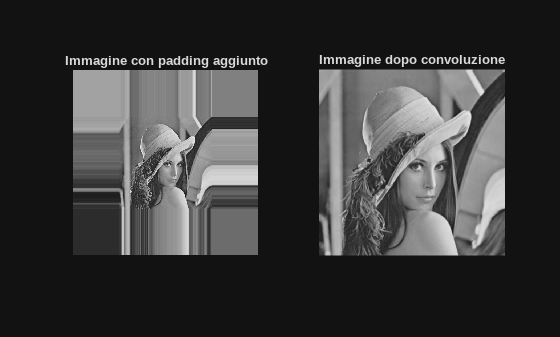

% Padding che replica l'immagine per altri 250 pixel in h e w
padded_img = padarray(single(I), [250, 250], 'replicate', 'both');

% Convolvi l'immagine con il kernel
conv_img = my_conv(single(padded_img), k_blur);
conv_img = conv_img(250:761,250:761); % immagine ritagliata
figure;
subplot(1, 2, 1);
imshow(uint8(padded_img));
title('Immagine con padding aggiunto');
subplot(1, 2, 2);
imshow(uint8(conv_img));
title('Immagine dopo convoluzione');

È possibile usare una versione ottimizzata della convoluzione che riduce i cili da 4 a 2, scansionando l'immagine con un solo indice e determinando l'intorno di un pixel usando una LookUp Table. Questo permette di evitare il calcolo di x e y.

Si può usare un'altra LUT per il Precalcolo dei Prodotti tra i valori del kernel e i 256 valori di grigio possibili, accedendo così al valore desiderato invece di calcolare il prodotto.

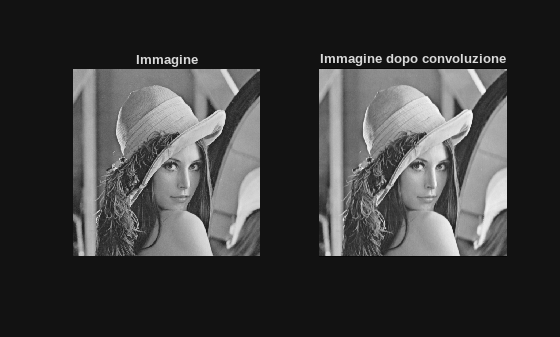

function tmp = convOneIndexLUT(img,ker) % per kernel 3x3
[h, w] = size(img);
[hk,wk] = size(ker);

tmp = zeros(h,w,"single"); % Inizializza l'immagine di output

% Machera per non considerare il bordo
tmp(2:end-1, 2:end-1) = 1;

% LUT per accesso con indice singolo con offset
firstLUT = [-h-1, -h, -h+1, -1, 0, +1, +h-1, +h, +h+1];

% Seconda LUT con precalcolo dei prodotti
prod = (0:255)';
secondLUT = prod * reshape(ker,1,[]);

% restituisce gli indici lineari di tutti gli elementi diversi da zero
for i = find(tmp)' 
    t = 0;
    for k = 1:hk
        t = t + secondLUT(img(firstLUT(k)+i) + 1, k);
    end
    tmp(i) = t;
end
tmp = uint8(tmp);
end

% Convolvi l'immagine con il kernel
conv_img2 = convOneIndexLUT(I, k_blur);
figure;
subplot(1, 2, 1);
imshow(I);
title('Immagine');
subplot(1, 2, 2);
imshow(conv_img2,[]);
title('Immagine dopo convoluzione');